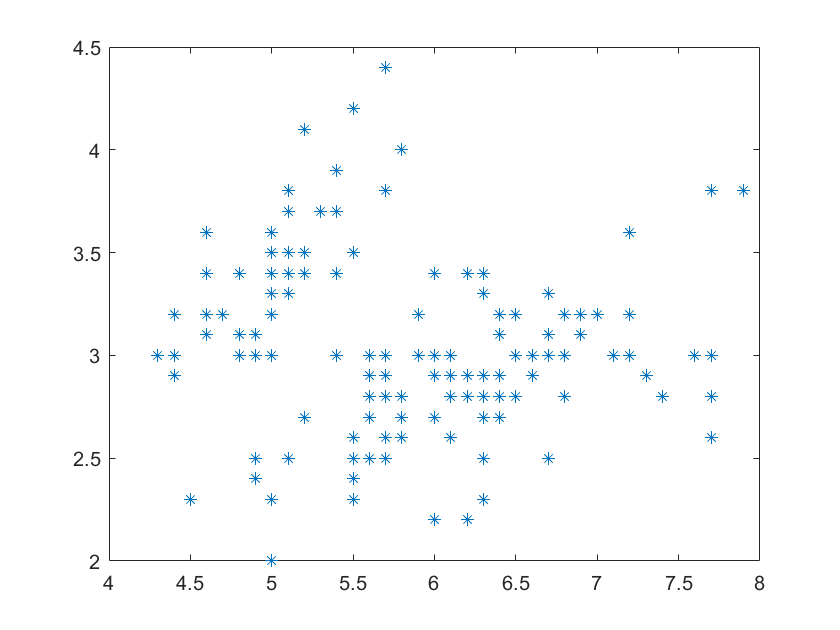

X = iris_dataset;
% 取均值
m = mean(X,2);
figure;
plot(X(1,:),X(2,:),'*');

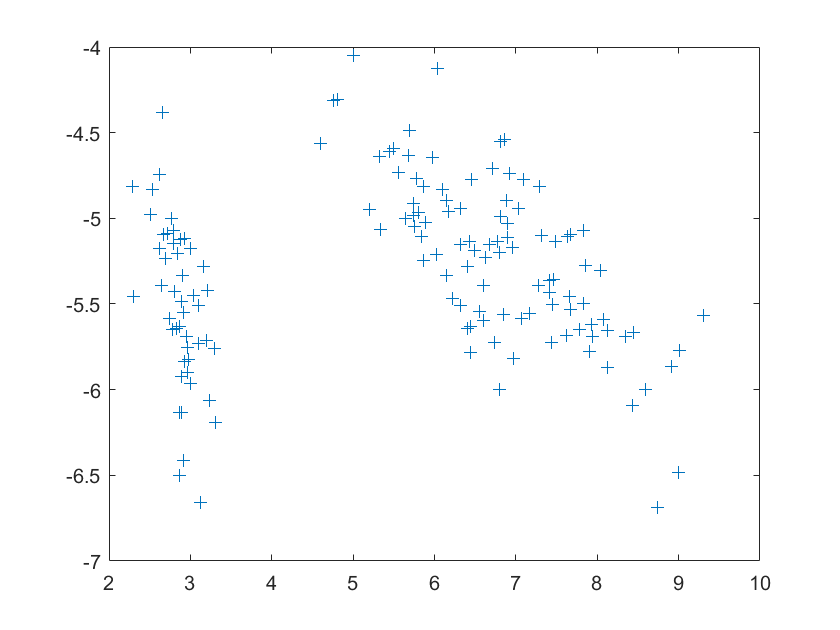

% 中心化处理
Xcen = X - m * ones(1,150);
% 求协方差矩阵
C = 1/150 * Xcen * Xcen';
% 奇异值分解
[V,D] = eig(C);
% 排序
[~ , inx] = sort(diag(D),'descend');
% 变换矩阵W
Wpca = V(:,inx(1:2));
% 样本主成分矩阵Xdim数据为2维
Xdim = Wpca'*X;
figure;
plot(Xdim(1,:),Xdim(2,:),'+');